## PERM - Jan Kaniuka (klasyfikacja i detekcja słów kluczowych)

grupa 8:15 - 9:45 

## Przetwarzanie i normalizacja danych

W tym miejscu następuje przygotowanie danych do dalszej analizy. Zależnie od wybranego sposobu liczenia cech może tutaj następować wyrównanie długości nagrań, normalizacja głośności, wycinanie gragmentów ciszy itp. 

for k=1:length(data)
    data{k} = preprocess(data{k});
end

## Ekstrakcja wektora cech

Dla każdego nagrania należy wyznaczyć jego reprezentację. Powinna ona być kompaktowa, mieć dużo wspólnych cech dla nagrań tego samego słowa oraz dobrze rozróżniać nagrania różnych słów. Powinna być też możliwie niezależna od mówcy (w tym zadaniu nie zależy nam na identyfikacji osób). Przykładowa implementacja wykorzystuje bardzo prostą cechę: moc sygnału w różnych częstotliwościach, bez normalizacji częstotliwości bazowej.

% wyznacz jedną cechę do określenia rozmiaru wektora
% zakładamy stały rozmiar wektora cech
tmp = extract(data{1}, fs);
feats = zeros(length(tmp), length(data));

% wyznaczenie cech dla wszystkich danych
for k=1:length(data)
    feats(:,k) = extract(data{k}, fs);
end

## Trening klasyfikatora

Podstawą treningu są wektory cech i etykiety danych trenujących. Wyjściem powinien być pewien model dostępnych klas. Zależnie od wybranego klasyfikatora może mieć on różną postać. W ramach przykładu przygotowane zostały dwa proste klasyfikatory: najbliższego sąsiada (1-NN) oraz geometryczny. Klasyfikator 1-NN nie potrzebuje żadnego dodatkowego przygotowania danych - zbiór treningowy jest jednocześnie uzwanany za model. W przypadku klasyfikatora geometrycznego dla każdej z klas wyznaczane są uśrednione wektory cech i to one są zwracane jako ostateczny model. 

[model1, labels1] = fit_1nn(feats(:, train_ids), train_lbl(train_ids));
[model2, labels2] = fit_geom(feats(:, train_ids), train_lbl(train_ids));

## Test klasyfikatora k-NN

Zaimplementowałem klasyfikator k-NN w dwóch wersjach: z głosowaniem większościowym oraz z ważeniem po odległości. Optymalna liczność sąsiadów ustalona na drodze eksperymentów to k=28. Największą skuteczność (accuracy) uzyskano dla metryki 'cityblock'. **Maksymalna uzyskana skuteczność klasyfikatora k-NN z głosowaniem większościowym to 48.61%. **Wynik nie jest najgorszy ponieważ, przy losowym wybieraniu etykiet skuteczność to 25%, a zaimplementowany klasyfikator ma tę skuteczność dwa razy większą. 

Wykorzystując wytrenowane modele i podzbiór testowy można wyznaczyć ich predykcje i określić skuteczność klasyfikacji.

cls1 = predict_knn(feats(:, test_ids), model1, labels1, 28, 'majority_voting', 'cityblock');

Znając oczekiwane etykiety dla klas można wyznaczyć skuteczność (liczbę poprawnych klasyfikacji):

all_labels = [train_lbl test_lbl];
cls_true = all_labels(test_ids);
acc1 = sum(cls1 == cls_true) / length(cls1)

acc1 = 0.4861

Dokładniejsza analiza błędów może być dokonana przy użyciu macierzy pomyłek:

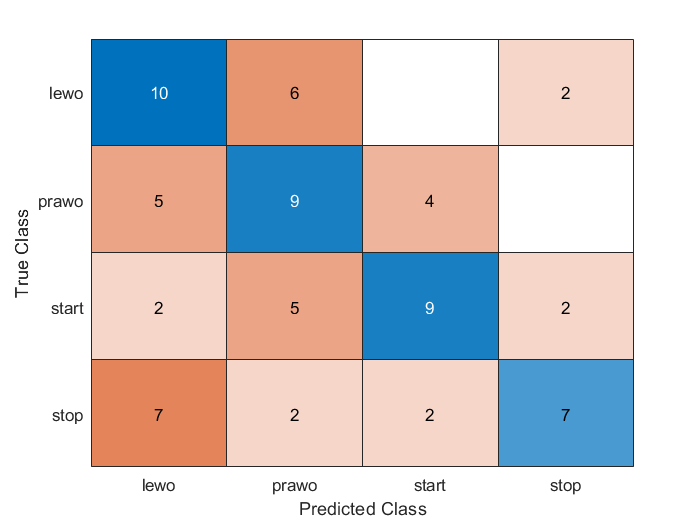

figure;
confusionchart(confusionmat(cls_true, cls1), names)

### **Porównanie dwóch wersji klasyfikatora k-NN**

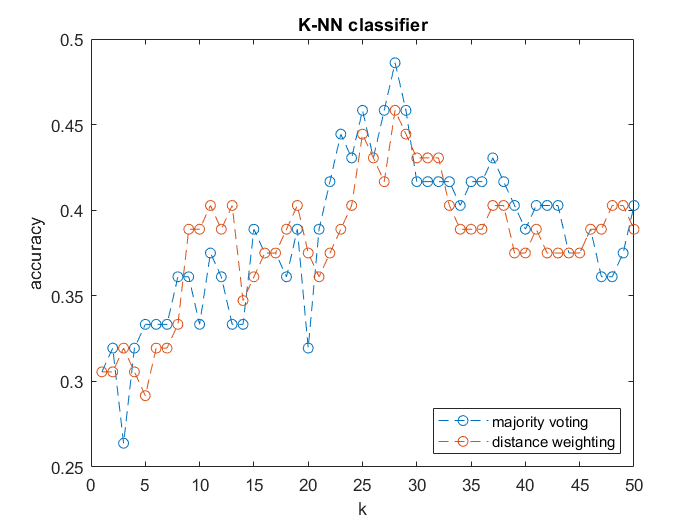

compare_knn(feats, test_ids, model1, labels1, train_lbl, test_lbl, 50, 'cityblock');

## Test klasyfikatora geometrycznego

cls2 = predict_geom(feats(:, test_ids), model2, labels2);
acc2 = sum(cls2 == cls_true) / length(cls2)

acc2 = 0.4306

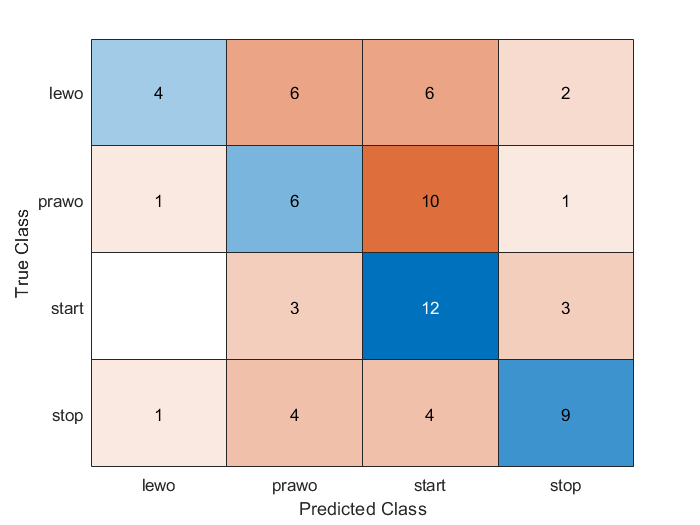

figure;
confusionchart(confusionmat(cls_true, cls2), names)

## Detekcja słów kluczowych w strumieniu

Dzieląc długie nagranie na (nakładające się) okna o ustalonej długości możemy każde z nich przepuścić przez wybrany klasyfikator. 

nagrania = {
    'stream/01/stream_1.wav'
%     'stream/02/stream_1.wav'
    'stream/03/stream_1.wav'
    'stream/04/stream_1.wav'
    'stream/05/stream_1.wav'
    'stream/06/stream_1.wav'
    'stream/07/stream_1.wav'
    'stream/08/stream_1.wav'
%     'stream/09/stream_1.wav'
    'stream/10/stream_1.wav'
    'stream/11/stream_1.wav'
%     'stream/12/stream_1.wav'
    'stream/13/stream_1.wav'
    'stream/14/stream_1.wav'
    'stream/15/stream_1.wav'
    'stream/16/stream_1.wav'
    'stream/17/stream_1.wav'
    'stream/18/stream_1.wav'
    'stream/19/stream_1.wav'
    'stream/20/stream_1.wav'
    'stream/21/stream_1.wav'
%     'stream/22/stream_1.wav'
    'stream/23/stream_1.wav'
};

opisy = {
    'stream/01/labels_1.txt'
%     'stream/02/labels_1.txt'
    'stream/03/labels_1.txt'
    'stream/04/labels_1.txt'
    'stream/05/labels_1.txt'
    'stream/06/labels_1.txt'
    'stream/07/labels_1.txt'
    'stream/08/labels_1.txt'
%     'stream/09/labels_1.txt'
    'stream/10/labels_1.txt'
    'stream/11/labels_1.txt'
%     'stream/12/labels_1.txt'
    'stream/13/labels_1.txt'
    'stream/14/labels_1.txt'
    'stream/15/labels_1.txt'
    'stream/16/labels_1.txt'
    'stream/17/labels_1.txt'
    'stream/18/labels_1.txt'
    'stream/19/labels_1.txt'
    'stream/20/labels_1.txt'
    'stream/21/labels_1.txt'
%     'stream/22/labels_1.txt'
    'stream/23/labels_1.txt'
};

jaccard_result = zeros(4,1);

for number=1:19
    stream = audioread(nagrania{number});
    
    len = round(0.8 * fs);
    overlap = round(0.1 * fs);
    
    cls = zeros(length(stream), 1);
    dst = zeros(length(stream), 1);
    
    for k=1:overlap:length(stream)-len
        r = stream(k:k+len);
        r = preprocess(r, fs);
        f = extract(r, fs);
        [cls(k:k+len), dst(k:k+len)] = predict_knn2(f, model1, labels1, 28);
    end
    
    cls_filt = cls;
    cls_filt(dst > 3) = 0;
    lbls = get_labels(nagrania{number}, opisy{number});
    acc_1 = sum(lbls == 1 & cls_filt == 1) / sum(lbls == 1 | cls_filt == 1);
    jaccard(cls_filt, lbls);
    
    jaccard_result = jaccard_result + jaccard(cls_filt, lbls);
end

### Analiza wyników

Poniżej zamieszczono statystyki dla słów kolejnych słów (kolejność taka, jak w funkcji generującej etykiety). Słabe działanie klasyfikatora wynika miezy innymi z niskiej jakości nagrań - w części z nich słowa nie są dobrze izolowane. Maksymalna skuteczność wykrywania jednego ze słów wynosiła około 38% - wizualizacja dla tego nagrania (numer 11) widoczna jest poniżej.

jaccard_result = jaccard_result/19

jaccard_result =     0.0327
    0.1000
    0.0691
    0.0801


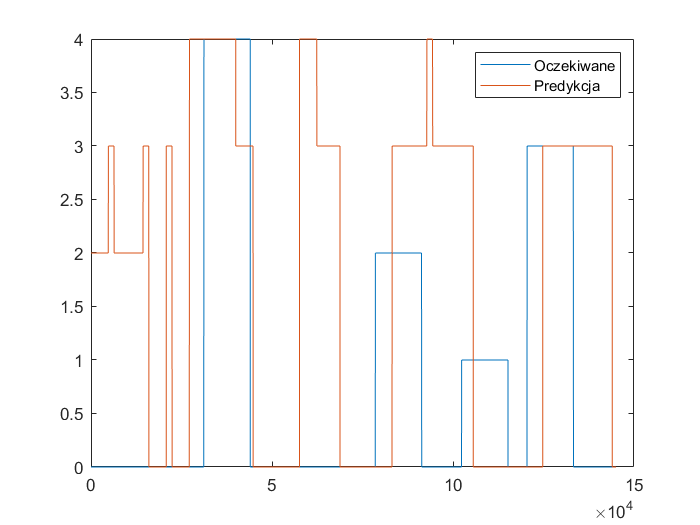

stream = audioread('stream/11/stream_1.wav');
    
    len = round(0.8 * fs);
    overlap = round(0.1 * fs);
    
    cls = zeros(length(stream), 1);
    dst = zeros(length(stream), 1);
    
    for k=1:overlap:length(stream)-len
        r = stream(k:k+len);
        r = preprocess(r, fs);
        f = extract(r, fs);
        [cls(k:k+len), dst(k:k+len)] = predict_knn2(f, model1, labels1, 28);
    end
    
    cls_filt = cls;
    cls_filt(dst > 3) = 0;
    lbls = get_labels('stream/11/stream_1.wav', 'stream/11/labels_1.txt');
    acc_1 = sum(lbls == 1 & cls_filt == 1) / sum(lbls == 1 | cls_filt == 1);
    
figure; plot(lbls); hold on; plot(cls_filt); legend("Oczekiwane", "Predykcja");

## Definicje funkcji

### Przetwarzanie wstępne

function y = preprocess(x, fs)
    y = x / max(x);
end

### Ekstrakcja wektora cech

function f = extract(x, fs)
    nfft = 256;
    f = pwelch(x, 1024, 256, nfft, fs);
    f = f / max(f);
end

### Klasyfikator 1-NN

function [model, labels] = fit_1nn(x, y)
    model = x;
    labels = y;
end

function [cls, dst] = predict_1nn(feats, model, labels)
    % wyznacz wszystkie odległości pomiędzy wektorami cech feats a modelem
    dm = pdist2(feats', model', 'cosine');
    
    % znajdź najmniejszą wartość dla każdego wiersza (próbki testowej)
    [dst, min_idx] = min(dm, [], 2);
    
    % określ klasę dla każdej próbki
    cls = labels(min_idx);
end

### Klasyfikator geometryczny

function [model, labels] = fit_geom(x, y)
    cls_num = max(y);
    
    model = zeros(size(x,1), cls_num);
    
    % średnia ze wszystkich kolumn o tej samej etykiecie klasy
    for k = 1:cls_num
        model(:,k) = mean(x(:, y==k), 2);
    end
    
    % po jednej wartości dla każdej klasy
    labels = 1:cls_num;
end

function [cls, dst] = predict_geom(feats, model, labels)
    % wyznacz wszystkie odległości pomiędzy wektorami cech feats a modelem
    dm = pdist2(feats', model', 'cosine');
    
    % znajdź najmniejszą wartość dla każdego wiersza (próbki testowej)
    [dst, min_idx] = min(dm, [], 2);
    
    % określ klasę dla każdej próbki
    cls = labels(min_idx);
end


### **Klasyfikator k-NN**

function [cls, dst] = predict_knn(feats, model, labels, k, type, metric)
    % wyznacz wszystkie odległości pomiędzy wektorami cech feats a modelem
    dm = pdist2(feats', model', metric);
    
    
    % znajdź k-najmniejszych wartości dla każdego wiersza (próbki testowej)
    [dst, min_idx] = mink(dm, k, 2);
    classes = labels(min_idx);
    
    if (k==1)
        classes = classes';
    end
    
    if (strcmp(type,'distance_weighting')) 
        [rows, cols] = size(classes);
        num_of_classes = 4;
        weighted_classes_raw = zeros(rows, num_of_classes);
        for row=1:rows
            for col=1:cols
                class_now = classes(row,col);
                inv_dist = 1/dst(row,col);
                if class_now == 1
                    weighted_classes_raw(row,1) = weighted_classes_raw(row,1) + inv_dist;
                elseif class_now == 2
                    weighted_classes_raw(row,2) = weighted_classes_raw(row,2) + inv_dist;
                elseif class_now == 3
                    weighted_classes_raw(row,3) = weighted_classes_raw(row,3) + inv_dist;
                elseif class_now == 4
                    weighted_classes_raw(row,4) = weighted_classes_raw(row,4) + inv_dist;               
                end
            end
        end
        
        weighted_classes_raw_idx = zeros(rows, 1);
        for j=1:rows
            [~, I] = max(weighted_classes_raw(j,:));
            weighted_classes_raw_idx(j) = I;
        end
        
        cls_k_n_weighted = weighted_classes_raw_idx';
        cls = cls_k_n_weighted;
        
    elseif (strcmp(type,'majority_voting'))
        M = mode(classes,2);
        cls_k_n = M';
        cls = cls_k_n;
    end
    
end

### **Porównanie działania **

function [] = compare_knn(feats, test_ids, model1, labels1, train_lbl, test_lbl, kmax, metric)
acc_vect_majority = zeros(kmax, 1);
for k=1:kmax
    cls1 = predict_knn(feats(:, test_ids), model1, labels1, k, 'majority_voting', metric);
    all_labels = [train_lbl test_lbl];
    cls_true = all_labels(test_ids);
    acc1 = sum(cls1 == cls_true) / length(cls1);
    acc_vect_majority(k) = acc1;
end

acc_vect_dist = zeros(kmax, 1);
for k=1:kmax
    cls1 = predict_knn(feats(:, test_ids), model1, labels1, k, 'distance_weighting', metric);
    all_labels = [train_lbl test_lbl];
    cls_true = all_labels(test_ids);
    acc1 = sum(cls1 == cls_true) / length(cls1);
    acc_vect_dist(k) = acc1;
end

figure;
plot(acc_vect_majority,'--o', 'LineWidth', 0.5);
hold on;
plot(acc_vect_dist,'--o', 'LineWidth', 0.5);
legend('majority voting', 'distance weighting', 'Location',"southeast");
title("K-NN classifier");
xlabel("k");
ylabel("accuracy");
end


### **Pozostałe funkcje**

function lbl = get_labels(stream, labels)
  M = containers.Map({'prawo', 'lewo', 'stop', 'start'}, [1 2 3 4]);

  [x, fs] = audioread(stream);
  lbl = zeros(size(x));
  
  fid = fopen(labels);
  txt = textscan(fid,'%s %f'); 
  
  for k=1:length(txt{2})
    ts = txt{2}(k) * fs;
    te = ts + 0.8 * fs;
    lbl(ts:te) = M(txt{1}{k});
  end
  
  lbl = lbl(1:size(x));
  
end

function [cls, dst] = predict_knn2(feats, model, labels, k)
    dm = pdist2(feats', model', 'cityblock');
    [dst_nn, min_idx] = mink(dm, k, 2);
    cls_nn = labels(min_idx);
    cls = mode(cls_nn, 2);
    for i=1:length(cls)
        inx = find(cls_nn(i,:)==cls(i));
        dst(i) = dst_nn(inx(1));
    end
    cls = cls';
    dst = dst';

end